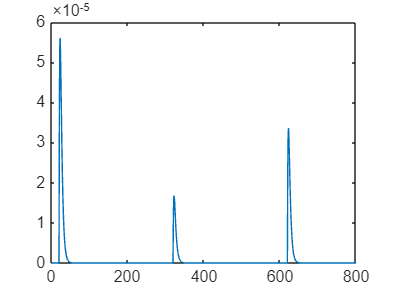

%% intro
clear all
rng("shuffle")
%rng(2,"twister")

run("main_channel.m")

newresponse = zeros(1,800);
newresponse(1:281) = Final_response(1:281);
newresponse(300:451) = Final_response(1:152)*0.3;
newresponse(600:751) = Final_response(1:152)*0.6;


H = Final_response;
H = newresponse;
%H = [1, 0, 0, 0, 0];


figure
plot(H)



%% 1) Parameters
numSymbols      = 247170;    % Number of BPSK symbols
samplesPerSym   = 10;       % Oversampling factor
rolloff         = 0.25;    % Rolloff factor
span            = 6;       % Filter span in symbols
snrDB           = 20;      % SNR (dB)

% Raised Cosine Filter
rcFilter = rcosdesign(rolloff, span, samplesPerSym, 'sqrt');
filtLen  = length(rcFilter); 
filtDelay= (filtLen - 1)/2;  % Group delay in samples

% Example channel impulse response
% Make it short to highlight the effect of zero-forcing
h_est = H; 

%% 2) Transmitter
% Generate random bits
txBits = randi([0,1], numSymbols, 1);
% BPSK mapping: 0 -> -1, 1 -> +1
txSymbols = 2*txBits - 1;
% Upsample
txUpsampled = upsample(txSymbols, samplesPerSym);

% Transmit filter (pulse shaping)
txFiltered = filter(rcFilter, 1, txUpsampled);

% Remove filter delay at TX for a "cleaner" start
% (Alternatively, you can keep it and handle at RX)
txFiltered = txFiltered(filtDelay+1 : end-filtDelay);


%% 3) Pass Through Channel (Time-Domain)
% Convolve with h_est 
txChannelOut = conv(txFiltered, h_est, 'full');


%%PREAMBLE OOK
% Parámetros de configuración
Fs = 410e3;            % Frecuencia de muestreo (Hz)
Rb = 1e3;            % Tasa de bits (bits/s)
Fc = 1e5;           % Frecuencia de la portadora (Hz)
samplesPreamb = 100;%Fs / Rb; % Muestras por bit
% Definir preámbulo y paquete de bits
preamble = [1,1,1,1,0,0,0,0,1,0,1,0,1,1,0,0]; % Ejemplo de preámbulo
% Generar pulsos para el preámbulo y el paquete
preambleStream = repelem(preamble, samplesPreamb);
bitStream = preambleStream;

% Generar la señal portadora
t = (0:length(bitStream)-1) / Fs; % Vector de tiempo
carrier = cos(2 * pi * Fc * t);
modulatedSignal = bitStream.* carrier;


%% PREAMBLE BPSK 1

% This block is RRC-filtered + convolved by H

pilotLen  = 16;    % number of pilot bits (adjust as needed)
pilotBits = [1 1 0 0  1 0 0 1  1 0 1 0  1 1 1 1];  % or use a fixed pattern
% Map bits to BPSK symbols: 0->-1, 1->+1
pilotBPSK = 2*pilotBits - 1;

% RRC filter design

% Upsample pilot bits
pilotUp = upsample(pilotBPSK, samplesPerSym);

% Pulse-shape with RRC
pilotRRCnoH = filter(rcFilter, 1, pilotUp);

%pilotChan = conv(pilotRRC, H, 'full');
% pilotChan is now the baseband pilot block after channel




%% PREAMBLE BPSK 2

% This block is RRC-filtered + convolved by H

pilotLen  = 16;    % number of pilot bits (adjust as needed)
pilotBits = [1 1 0 0  1 0 0 1  1 0 1 0  1 1 1 1];  % or use a fixed pattern
% Map bits to BPSK symbols: 0->-1, 1->+1
pilotBPSK = 2*pilotBits - 1;

% RRC filter design

% Upsample pilot bits
pilotUp = upsample(pilotBPSK, samplesPerSym);

% Pulse-shape with RRC
pilotRRC = filter(rcFilter, 1, pilotUp);

% Convolve with artificial channel H
pilotChan = conv(pilotRRC, H, 'full');
% pilotChan is now the baseband pilot block after channel

% Parámetros
Fs = 410e3; % Frecuencia de muestreo (Hz)
T = 0.2;    % Duración del ruido (segundos)
N = Fs * T; % Número de muestras

% Generar ruido pseudoaleatorio uniforme
rng(123); % Semilla para reproducibilidad
noise_uniform = rand(1, N); % Ruido uniforme entre [0, 1]

% Generar ruido pseudoaleatorio gaussiano
rng(123); % Semilla para reproducibilidad
noise_gaussian = randn(1, N); % Ruido gaussiano con media 0 y varianza 1

% Representación gráfica
t = (0:N-1) / Fs; % Vector de tiempo



%Aplicar canal modulador al paquete
noise_gaussianH = conv(noise_gaussian,H,'same');
MAX_H=max(noise_gaussianH);
noise_gaussianH = noise_gaussianH/MAX_H;




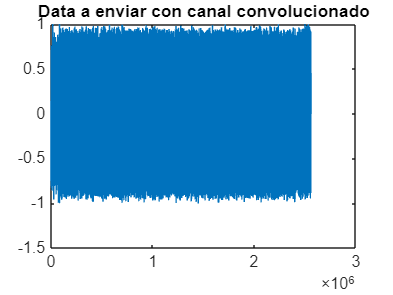

BPSK_segms = [pilotRRCnoH/max(pilotRRCnoH), pilotChan/max(pilotChan), txChannelOut'/max(txChannelOut)];

zeropadding = zeros(5000,1)';

modulatedSignalTx = [noise_gaussianH, modulatedSignal, BPSK_segms,zeropadding]*1;

write_float_binary(modulatedSignalTx,'envioOOKyDATA.bin');

read = read_float_binary('envioOOKyDATA.bin')';

figure
plot(read(1:end))
title("Data a enviar con canal convolucionado")

%pyrunfile("TXRXscript.py")

function v = write_float_binary (data, filename)

  %% usage: write_float_binary (data, filename)
  %%
  %%  open filename and write data to it as 32 bit floats
  %%

  m = nargchk (1,2,nargin);
  if (m)
    usage (m);
  end

  f = fopen (filename, 'wb');
  if (f < 0)
    v = 0;
  else
    v = fwrite (f, data, 'float');
    fclose (f);
  end
end


function v = read_float_binary (filename, count)

  %% usage: read_float_binary (filename, [count])
  %%
  %%  open filename and return the contents, treating them as
  %%  32 bit floats
  %%

  m = nargchk (1,2,nargin);
  if (m)
    usage (m);
  end

  if (nargin < 2)
    count = Inf;
  end

  f = fopen (filename, 'rb');
  if (f < 0)
    v = 0;
  else
    v = fread (f, count, 'float');
    fclose (f);
  end
end

function bits = demodulate_signal(signal, samples_per_bit)
    % Inicializar vector de bits
    num_bits = length(signal) / samples_per_bit;
    bits = zeros(1, num_bits);

    % Determinar el valor de cada bit
    for i = 1:num_bits
        segment = signal((i-1)*samples_per_bit + 1 : i*samples_per_bit);
        if mean(segment) > 0
            bits(i) = 1;
        else
            bits(i) = 0;
        end
    end
end


function ber = calculate_ber(bits_received, bits_original)
    % Verificar que los arreglos tengan la misma longitud
    if length(bits_received) ~= length(bits_original)
        error('Los arreglos de bits deben tener la misma longitud');
    end
    
    % Calcular el número de errores
    num_errors = sum(bits_received ~= bits_original);
    
    % Calcular el BER
    ber = num_errors / length(bits_original);
end

